x = 0:0.1:2; y = [0:0.1:2]';
[X,Y] = meshgrid(0:0.1:2,0:0.1:2);

Potenziale attrattivo

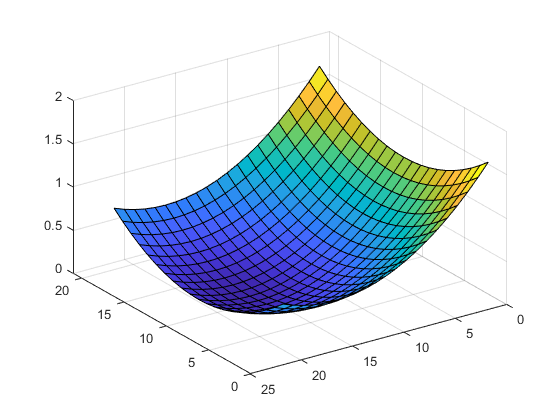

xg = 1; yg = 1.5; 
Ua = 1/2*((yg-y).^2 + (xg-x).^2);
surf(Ua)
view([-116.70 18.96]);

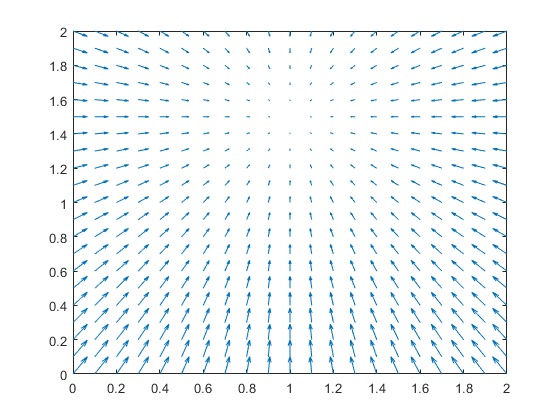

[gx,gy] = gradient(-Ua);
quiver(X,Y,gx,gy)

Potenziale repulsivo 1

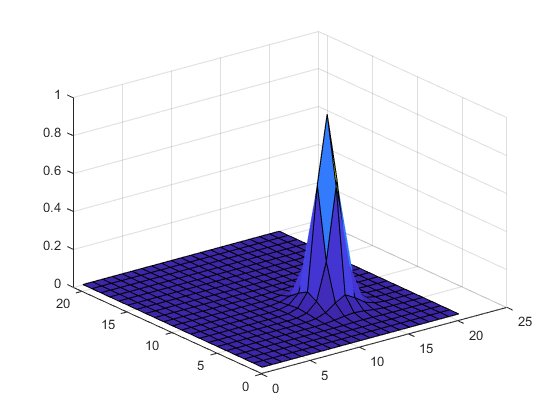

xo = 1.3; yo = 0.7;
d = sqrt((x-xo).^2 + (y-yo).^2);
Ur =  1/100*((1./d - 1/0.5).^2);
Ur(d > 0.5) = 0; Ur(Ur>100) = 1;
surf(Ur)

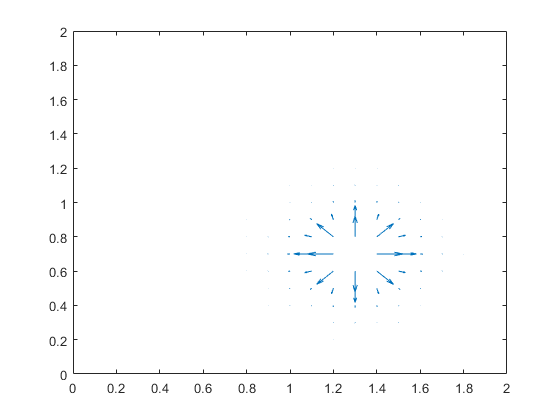

[gx,gy] = gradient(-Ur);
quiver(X,Y,gx,gy)

Potenziale respulsivo 2

% xo = 0.7; yo = 0.7;
% d2 = sqrt((x-xo).^2 + (y-yo).^2);
% Ur2 =  1/100*((1./d2 - 1/0.5).^2);
% Ur2(d2 > 0.5) = 0; Ur2(Ur2 > 100) = 1;
% Ur = Ur + Ur2;

Potenziale totale

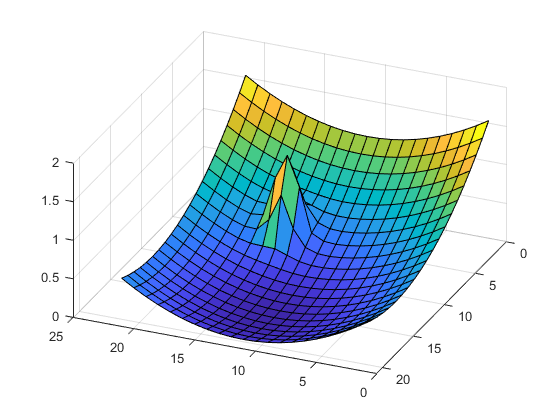

U = Ur + Ua;
surf(U)
view([-156.78 42.96]);

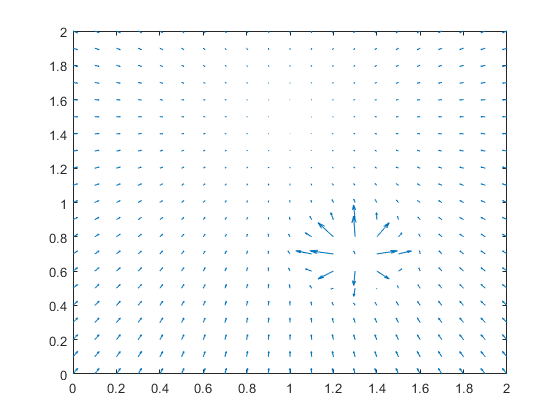

[gx,gy] = gradient(-U);
quiver(X,Y,gx,gy)

r = robot(1.5,0);
grid = Grid(10,0,2);
act = Act(r,grid);
for i = 1 : 100
    act.move(grid);
end

Potenziale elicoidale

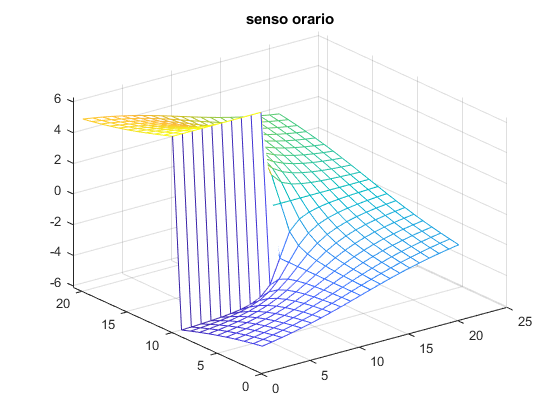

x0 = 1; y0 = 1;
c = 2;

% Forma parametrica
% clearvars
% syms u v r t;
% r = v; t = u;
% x = x0 + 1.5*cos(t);
% y = [y0 + 1.5*sin(t)]';
% z = c*t;
% fsurf(x,y,z,[0 2*pi]);

%Forma cartesiana
pot1 = c*atan2(y-y0,x-x0);
mesh(pot1); title("senso orario");

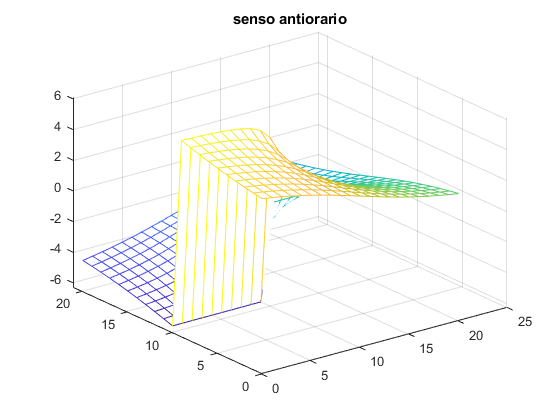

pot2 = -c * atan2(y-y0,x-x0);
mesh(pot2); title("senso antiorario");

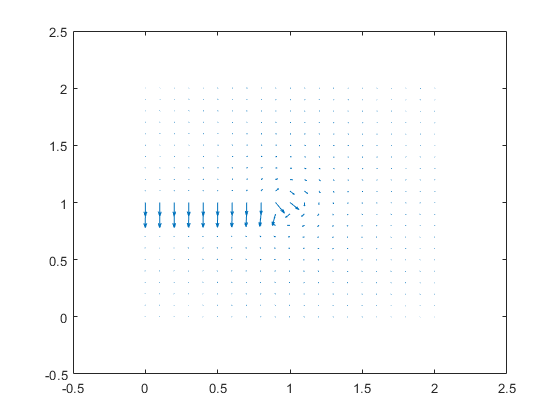

[gx1,gy1] = gradient(pot2);

gx = c*(y-y0)./((x-x0).^2+(y-y0).^2);
gy = c*(x0-x)./((x-x0).^2+(y-y0).^2);

figure;
quiver(X,Y,gx1,gy1);

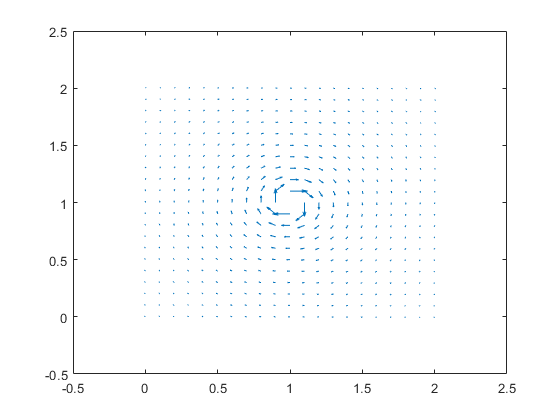

quiver(X,Y,gx,gy);

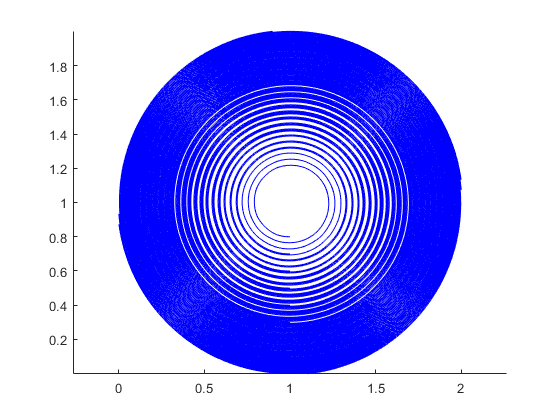

starty = 0.1:0.1:1;
startx = ones(size(starty));
figure;
streamline(X,Y,gx,gy,startx,starty);
axis equal